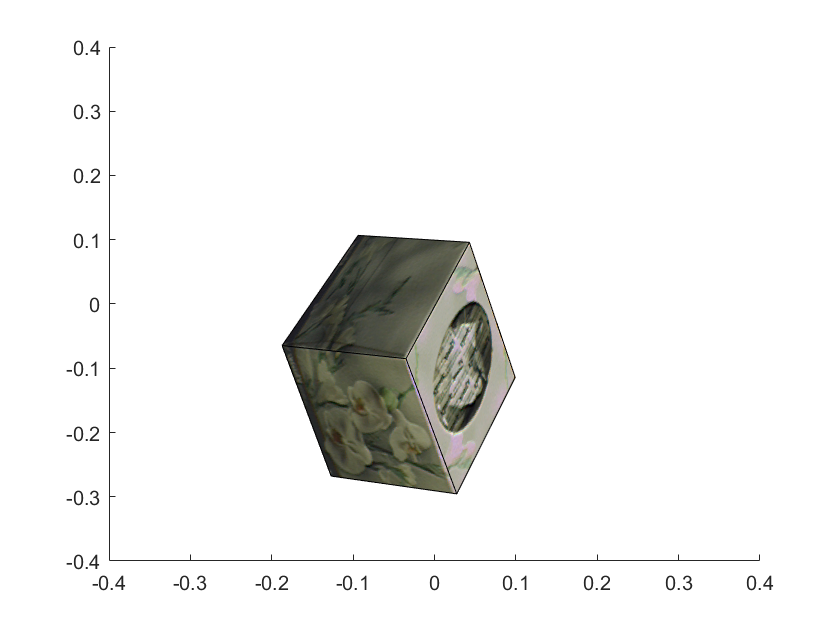

load ./data/corners.mat;
figure;
Pl= getCamera(corners_3D, leftpts);
Pr= getCamera(corners_3D, rightpts);

A_l = [363,269]; A_r = [240,273]; A_3D =  triangulate(A_l, A_r, Pl, Pr);
B_l = [444,163]; B_r = [343,162]; B_3D =  triangulate(B_l, B_r, Pl, Pr); 
C_l = [205,191]; C_r = [144,226]; C_3D =  triangulate(C_l, C_r, Pl, Pr); 
D_l = [293,95];  D_r = [242,124]; D_3D =  triangulate(D_l, D_r, Pl, Pr); 
E_l = [342,399]; E_r = [317,384]; E_3D =  triangulate(E_l, E_r, Pl, Pr); 
F_l = [198,327]; F_r = [224,338]; F_3D =  triangulate(F_l, F_r, Pl, Pr); 
G_l = [421,284]; G_r = [407,279]; G_3D =  triangulate(G_l, G_r, Pl, Pr); 

% same analysis as before
H_3D_1 = E_3D - A_3D + D_3D;
H_3D_2 = D_3D - C_3D + F_3D;
H_3D_3 = F_3D - E_3D + G_3D;
H_3D = (H_3D_1+H_3D_2+H_3D_3)./3.0;

hold on;
%read image
img_l=single(imread(fullfile('.','data','kleenex_left.bmp')));
img_r=single(imread(fullfile('.','data','kleenex_right.bmp')));
% get the texture of facet 1,2,3 and draw them, return the texture matrixs 
text1 = Texture(img_l,A_l,A_3D,B_l,B_3D,C_l,C_3D,D_l,D_3D);
text2 = Texture(img_l,A_l,A_3D,E_l,E_3D,C_l,C_3D,F_l,F_3D);
text3 = Texture(img_r,A_r,A_3D,E_r,E_3D,B_r,B_3D,G_r,G_3D);

axis([-0.4 0.4 -0.4 0.4]);

% use the texture matrixs got before to draw the texture on  facet 4,5,6 by sssuming the symmetry 

DrawTexture(text1,E_3D,G_3D,F_3D,H_3D);
DrawTexture(text2,B_3D,G_3D,D_3D,H_3D);
DrawTexture(text3,C_3D,F_3D,D_3D,H_3D);

# Local Functions

function P = getCamera(X3, X2)
    % Problem 3(a)
    % the function that computes the 3x4 camera matrix P from nx3
    % world coordinates X3 and an nx2 matrix of pixel coordinates X2
    % representing the projection of the world points into a single 
    % projective camera
    
    % replace the next line with your own code
    P = zeros(3,4);
    T2 = getT(X2);
    T3 = getTFor3D(X3);
    % first of all, we need to normalize the points
    
    X2_transform = transform(T2, X2);  % normalize the two points set
    X3_transform = transform(T3, X3);
    
    % To construct Ai
    
    Num = size(X2_transform);
    % Ai= [0,0,0,-w2*Point1,y2*Point2]
    % for homogenous coordiante, w1 = w2 = 1

    % using direct linear transform to get the projective matrix H
    % the DLT_transform is the function I wrote for this problem
    P_transform = DLT_transform(X3_transform,X2_transform,Num(1));

    % denormalization 
    % H = inv(T2)*(H_transform*T3); 

    P = T2\(P_transform*T3); 
    
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% optional functions for problem 3(c)


function X = triangulate(x1, x2, P1, P2)
    % Problem 4(b)
    % write a function that takes camera matrix P1 and P2, and image
    % points x1, x2 and estimates the 3D world points X 
    
    % replace the next line with your own code
    A = zeros(6,4);    
    %A(1:,) = yP3T-wP2T
    points_num = size(x1);
    X = zeros(points_num(1,1),3);
    P1_1T = P1(1,:); P1_2T = P1(2,:); P1_3T = P1(3,:); 
    P2_1T = P2(1,:); P2_2T = P2(2,:); P2_3T = P2(3,:); 
    
    % construct the A matrix analyzed above and used the SVD method to calculate AX=0  
    for i =1:points_num(1,1)
    point_x1 = double(x1(i,1));point_y1 = double(x1(i,2));point_w1 = 1.0;
    point_x2 = double(x2(i,1));point_y2 = double(x2(i,2));point_w2 = 1.0;
    A(1,:) = point_y1.*P1_3T-point_w1.*P1_2T;
    A(2,:) = point_w1.*P1_1T-point_x1.*P1_3T;
    A(3,:) = point_x1.*P1_2T-point_y1.*P1_1T;
    A(4,:) = point_y2.*P2_3T-point_w2.*P2_2T;
    A(5,:) = point_w2.*P2_1T-point_x2.*P2_3T;
    A(6,:) = point_x2.*P2_2T-point_y2.*P2_1T;
    [U,D,V] = svd (A);
    size_V=size(V);
    X_inhomo=V(:,size_V(2));
    P = A*X_inhomo;
    X(i,:) = inhomogenize(X_inhomo');
    end 
    %X N*3
    
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% optional functions for bonus questions

function DrawCamera(P,img_row,img_col) 
    
    % calculate the camera center

     M = P(:,1:3);
     P4 = P(:,4);
     C_inhomo = -1.0.*(M\P4);
     C = [C_inhomo;1];
     fprintf ("The center of this camera is (%f  %f  %f)", C(1),C(2),C(3)); 
     
     % set the image border and image centerpoint 
     Border1=[1,1]';
     Border2=[img_col,1]';
     Border3=[1,img_row]';
     Border4=[img_col,img_row]';
     
     image_center = [img_col/2,img_row/2]';

     P_inverse = P'/(P*P');
     % calculate the 3D world coordinate of these points
     Border1_3D = GetWorldCoordinate(Border1,P_inverse); 
     Border2_3D = GetWorldCoordinate(Border2,P_inverse); 
     Border3_3D = GetWorldCoordinate(Border3,P_inverse); 
     Border4_3D = GetWorldCoordinate(Border4,P_inverse);
     
     image_center_3D = GetWorldCoordinate(image_center,P_inverse);
     
     % get the camera_oriention and its field view
     camera_oriention = image_center_3D - C_inhomo;
     field_of_view1 = Border1_3D - C_inhomo;
     field_of_view2 = Border2_3D - C_inhomo;
     field_of_view3 = Border3_3D - C_inhomo;
     field_of_view4 = Border4_3D - C_inhomo;
     
     fprintf("The camera_oriention is vector (%f  %f  %f)", camera_oriention(1),camera_oriention(2),camera_oriention(3));
     fprintf("The field_of_view of camera is surrounded by four rays whose center is (%f  %f  %f)\n and directions are (%f  %f  %f), (%f  %f  %f), (%f  %f  %f)\n and (%f  %f  %f)\n", ...
         C(1),C(2),C(3),field_of_view1(1),field_of_view1(2),field_of_view1(3),... 
         field_of_view2(1),field_of_view2(2),field_of_view2(3),...
         field_of_view3(1),field_of_view3(2),field_of_view3(3),...
         field_of_view4(1),field_of_view4(2),field_of_view4(3));
     
     % try to select a small value in order to draw the camera approxipately 
     r = 0.25;
     Border1_3D = inhomogenize((r*[Border1_3D;1]+(1-r)*C)')';
     Border2_3D = inhomogenize((r*[Border2_3D;1]+(1-r)*C)')';
     Border3_3D = inhomogenize((r*[Border3_3D;1]+(1-r)*C)')';
     Border4_3D = inhomogenize((r*[Border4_3D;1]+(1-r)*C)')';
     
     % draw the lines of the pentahedron
     X1 = [C(1,1),Border1_3D(1,1),C(1,1),Border2_3D(1,1),C(1,1),Border3_3D(1,1),C(1,1),Border4_3D(1,1),Border3_3D(1,1),Border1_3D(1,1),Border2_3D(1,1),Border4_3D(1,1)];
     Y1 = [C(2,1),Border1_3D(2,1),C(2,1),Border2_3D(2,1),C(2,1),Border3_3D(2,1),C(2,1),Border4_3D(2,1),Border3_3D(2,1),Border1_3D(2,1),Border2_3D(2,1),Border4_3D(2,1)];
     Z1 = [C(3,1),Border1_3D(3,1),C(3,1),Border2_3D(3,1),C(3,1),Border3_3D(3,1),C(3,1),Border4_3D(3,1),Border3_3D(3,1),Border1_3D(3,1),Border2_3D(3,1),Border4_3D(3,1)];

     plot3(X1,Y1,Z1, 'color', 'red');
     
end


function new_img = Texture(img,A_2D,A_3D,B_2D,B_3D,C_2D,C_3D,D_2D,D_3D)

img_R = img(:,:,1);
img_G = img(:,:,2);
img_B = img(:,:,3);

% the 2d image coordinate of the 3D world coordinate
X1 = [double(A_2D);double(B_2D);double(C_2D);double(D_2D)];
X2 = [0.0,0.0;point_distance(A_3D,B_3D),0.0;0.0,point_distance(A_3D,C_3D);point_distance(A_3D,B_3D),point_distance(B_3D,D_3D)];

% set the cropborder
CropBorder = [0.0,point_distance(A_3D,B_3D),0.0,point_distance(B_3D,D_3D)]; 

H = getH(X1, X2);
text_R = uint8(applyH(img_R, H, CropBorder));
text_G = uint8(applyH(img_G, H, CropBorder));
text_B = uint8(applyH(img_B, H, CropBorder));
% use applyH(img, H, CropBorder) function to crop the texture part of the image

new_img_size = size(text_R);
new_img = zeros(new_img_size(1,1),new_img_size(1,2),3,'uint8');
new_img(:,:,1) = text_R;
new_img(:,:,2) = text_G;
new_img(:,:,3) = text_B;
% imwrite(new_img,'text1.bmp');
% im=imread(fullfile('.','text1.bmp'));

% use surf fcuntionin DrawTexture function to draw image
DrawTexture(new_img,A_3D,B_3D,C_3D,D_3D)

end

function DrawTexture(img,A,B,C,D)

s=surf([A(1,1) B(1,1);C(1,1)  D(1,1)],[A(1,2) B(1,2);C(1,2) D(1,2)],[A(1,3) B(1,3);C(1,3) D(1,3)]);
set(s,'facecolor','texturemap','cdata',img);

end

function d = point_distance(X,Y)
    d = sqrt(sum((X-Y).^2));
end

function DrawLines(lines_p1,color)

   lines_p1_size = size(lines_p1);
   N = lines_p1_size(1,1)/2;
   % draw lines, 2 points are grouped as a pair
   for i = 1:N
       Point1 = lines_p1(2*i-1,:);
       Point2 = lines_p1(2*i,:);
       X1 = [Point1(1,1),Point2(1,1)];
       Y1 = [Point1(1,2),Point2(1,2)];
       Z1 = [Point1(1,3),Point2(1,3)];
       plot3(X1,Y1,Z1, 'color', color);  
   end
end


function X3 = GetWorldCoordinate(X2, P_inverse)
       %X2 2*1
       X2_homo = [X2;1];
       X3_inhomo = P_inverse*X2_homo;
       X3 = inhomogenize(X3_inhomo')';
       %X3 3*1
end    

function T = getTFor3D(X)
% Question 1(b)
% Similarity matrix T that normalizes a set of 2D points. Input
% X is an Nx2 array of inhomgeneous image coordinates. Output is
% an invertible 3x3 matrix.

% check input
if ((~ismatrix(X)) || (size(X, 2) ~= 3) || (size(X, 1) == 0))
	error('Input must be an Nx3 array.');
end

% replace the next line with your own code
T=diag([2,2,1,1]);
Point_X = X(:,1); % get the x coordinates of the points
Point_Y = X(:,2); % get the y coordinates of the points
Point_Z = X(:,3); % get the z coordinates of the points
N_2 = size(X);
N = N_2(1);
% set m vector with mi is the varible mentioned in the text part of this problem

m = sqrt(Point_X.^2+Point_Y.^2 + Point_Z.^2-2.0*sum(Point_X)*Point_X/double(N)-2.0*sum(Point_Y)*Point_Y/double(N)-2.0*sum(Point_Z)*Point_Z/double(N)+(   (sum(Point_X))^2  +  (sum(Point_Y))^2 +  (sum(Point_Z))^2 )/double(N^2) );

% calculate s, tx, ty, tz using the equation in the text part
s = sqrt(3.0)*double(N)/ sum(m);
tx = sum(Point_X)*s/double(0-N);
ty = sum(Point_Y)*s/double(0-N);
tz = sum(Point_Z)*s/double(0-N);
%fprintf('%d,   %d,    %d\n',s,tx,ty);
%constuct the similarity transformation matrix 
T(1,1) = s; T(2,2) = s; T(3,3) = s; T(1,4) = tx; T(2,4) = ty; T(3,4) = tz; 

end % end function getT

function T = getT(X)
% Question 1(b)
% Similarity matrix T that normalizes a set of 2D points. Input
% X is an Nx2 array of inhomgeneous image coordinates. Output is
% an invertible 3x3 matrix.

% check input
if ((~ismatrix(X)) || (size(X, 2) ~= 2) || (size(X, 1) == 0))
	error('Input must be an Nx2 array.');
end

% replace the next line with your own code
T=diag([2,2,1]);
Point_X = X(:,1); % get the x coordinates of the points
Point_Y = X(:,2); % get the y coordinates of the points
N_2 = size(X);
N = N_2(1);
% set m vector with mi is the varible mentioned in the text part of this problem

m = sqrt(Point_X.^2+Point_Y.^2-2.0*sum(Point_X)*Point_X/double(N)-2.0*sum(Point_Y)*Point_Y/double(N)+(   (sum(Point_X))^2  +  (sum(Point_Y))^2  )/double(N^2) );

% calculate s, tx, ty using the equation in the text part
s = sqrt(2.0)*double(N)/ sum(m);
tx = sum(Point_X)*s/double(0-N);
ty = sum(Point_Y)*s/double(0-N);
%fprintf('%d,   %d,    %d\n',s,tx,ty);
% constuct the similarity transformation matrix 
T(1,1) = s; T(2,2) = s; T(1,3) = tx; T(2,3) = ty; 

end % end function getT


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function H = getH(X1, X2)
% Question 2(a)
% Homography that maps points in X1 to points in X2. Inputs
% X1, X2 are Nx2 arrays of inhomgeneous image coordinates. Output is
% an invertible 3x3 matrix. Requires function getT().

% check input
if ((~ismatrix(X1)) || (~ismatrix(X2)) || ~isempty(find(size(X1) ~= size(X2), 1))...
		|| (size(X1, 2) ~= 2) || (size(X1, 1) == 0))
	error('Input must be two Nx2 matrices.');
end

% replace the next line with your own code
H = eye(3);

% the first step is normalization of x
T1=getT(X1);  % get the similarity transformion matrix T
T2=getT(X2);
X1_transform = transform(T1, X1);  % normalize the two points set
X2_transform = transform(T2, X2);
Num = size(X1_transform);
% Ai= [0,0,0,-w2*Point1,y2*Point2]
% for homogenous coordiante, w1 = w2 = 1

% using direct linear transform to get the projective matrix H
% the DLT_transform is the function I wrote for this problem
H_transform = DLT_transform_2D(X1_transform,X2_transform,Num(1));

% denormalization 
% H = inv(T2)*(H_transform*T1); 

H = T2\(H_transform*T1); 

end % end function getH

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function Iout = applyH(Iin, H, CropBorder)
% Question 2(b)
% Warp image Iin using homography H. Inputs are image Iin
% and 3x3 invertible matrix H. Output is image Iout, possibly of different
% height and width than input.

% replace the next line with your own code
%Iout = Iin;
I = Iin;
[img_in_row,img_in_col] = size(I);

xmin = CropBorder(1,1); 
xmax = CropBorder(1,2);
ymin = CropBorder(1,3); 
ymax = CropBorder(1,4);
% cut the image by setting the border of the new image as the CropBorder of the texture
 
num_x_pts = img_in_col;  % set the resoution of the new image the same as the original image  
num_y_pts = img_in_row;

[x,y]=meshgrid(linspace(xmin,xmax,num_x_pts), linspace(ymin,ymax,num_y_pts));

% reshape them so that a homography can be applied to all points in parallel
X_=[x(:) y(:)];
X_size = size(X_);
% add the 3rd dimensional coordinate as 1
X = [X_';ones(X_size(1),1)'];

% [Apply a homography to homogeneous coordinates corresponding to ‘X’. ] %
Xn = H\X; % 3*n matrix
% [Compute inhomogeneous coordinates of mapped points. ] %
Xh = inhomogenize(Xn');
% [Save result in Nx2 matrix named ‘Xh’. ] %

% interpolate I to get intensity values at image points ‘Xh’
Ih=interp2(I,Xh(:,1),Xh(:,2),'linear');

% reshape intensity vector into image with correct height and width
Iout=reshape(Ih,[num_y_pts,num_x_pts]);

% Points in ‘Xh’ that are outside the boundaries of the image are assigned
% value ‘NaN’, which means ‘not a number’. The final step is to
% set the intensities at these points to zero.
Iout(find(isnan(Iout)))=0;

end % end function applyH

% Xn is a N*3 matrix with homogenous coordinate, return a N*2 matrix with inhomogenous coordinate
function result = inhomogenize(Xn)
    N_2 = size(Xn);
    if N_2(2) == 3
       Xni = Xn(:,1:2)./repmat(Xn(:,3),[1 2]);
       result = Xni(:,1:2);
    end
    if N_2(2) == 4
       Xni = Xn(:,1:3)./repmat(Xn(:,4),[1 3]);
       result = Xni(:,1:3);
    end
end

function result=transform(T, X)  % using the similar matrix to pre-normalize the points set 
% transform the point into another points using tansformation T
    N_2 = size(X);
    Xn = (T*[X'; ones(1,N_2(1))])';
% inhomogenize
    result = inhomogenize(Xn);
end

% using SVD to calcuate the over-dertemined equation
function H_transform=Calculate3X4P_UsingSVD(A)
    [U,D,V] = svd (A);
    size_V=size(V);
    result=V(:,size_V(2));
    H_transform = reshape(result,4,3);
    H_transform = H_transform';
end

% using DLT transform to calculate transformation matrix H of the normalized points set

function H_transform = DLT_transform(X1_Transform,X2_Transform,Num)

A = zeros(Num*2,12,'double');
for i=1:Num
    Point1 = X1_Transform(i,1:3);
    Point2 = X2_Transform(i,1:2);
    A(2*i-1,:) = [0,0,0,0,0.0-Point1(1),0.0-Point1(2),0.0-Point1(3),0.0-1,Point2(2)*Point1(1),Point2(2)*Point1(2),Point2(2)*Point1(3),Point2(2)];
    A(2*i,:)=[Point1(1),Point1(2),Point1(3),1,0,0,0,0,(0.0-Point2(1))*Point1(1),(0.0-Point2(1))*Point1(2),(0.0-Point2(1))*Point1(3),(0.0-Point2(1))];
    
end

H_transform = Calculate3X4P_UsingSVD(A);

end

function H_transform=Calculate3X3H_UsingSVD(A)
    [U,D,V] = svd (A);
    size_V=size(V);
    result=V(:,size_V(2));
    H_transform = reshape(result,3,3);
    H_transform = H_transform';
end

% using DLT transform to calculate transformation matrix H of the normalized points set
function H_transform = DLT_transform_2D(X1_Transform,X2_Transform,Num)

A = zeros(Num*2,9,'double');
for i=1:Num
    Point1 = X1_Transform(i,1:2);
    Point2 = X2_Transform(i,1:2);
    A(2*i-1,:) = [0,0,0,0.0-Point1(1),0.0-Point1(2),0.0-1,Point2(2)*Point1(1),Point2(2)*Point1(2),Point2(2)];
    A(2*i,:)=[Point1(1),Point1(2),1,0,0,0,(0.0-Point2(1))*Point1(1),(0.0-Point2(1))*Point1(2),(0.0-Point2(1))];
    
end
H_transform = Calculate3X3H_UsingSVD(A);

end
